# 粒子群算法寻找最值点：y = sin(10*pi*x) / x

[(22条消息) 粒子群优化算法（PSO）简介及MATLAB实现_pso对比算法_奔跑的Yancy的博客-CSDN博客](https://blog.csdn.net/lyxleft/article/details/82978362)

## I. 清空环境

clc
clear all

## II. 绘制目标函数曲线图

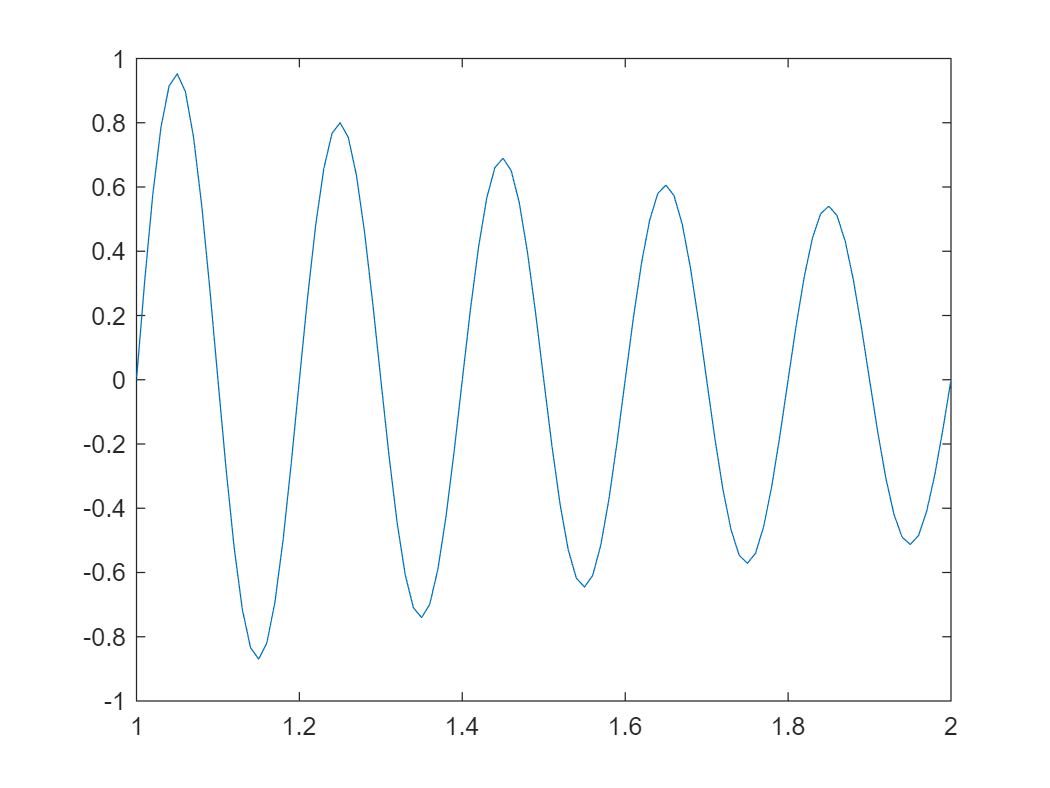

x = 1:0.01:2;
y = sin(10*pi*x) ./ x;
figure
plot(x, y)
hold on

## III. 参数初始化

c1 = 1.49445;
c2 = 1.49445;
 
maxgen = 50;   % 进化次数  
sizepop = 10;   %种群规模
 
Vmax = 0.5;   %速度的范围，超过则用边界值。
Vmin = -0.5;  
popmax = 2;   %个体的变化范围
popmin = 1;

## IV. 产生初始粒子和速度

for i = 1:sizepop
    % 随机产生一个种群
    pop(i,:) = (rands(1) + 1) / 2 + 1;    %初始种群，rands产生(-1,1)，调整到(1,2)
    V(i,:) = 0.5 * rands(1);  %初始化速度
    % 计算适应度
    fitness(i) = fun(pop(i,:));   
end

## V. 个体极值和群体极值

[bestfitness bestindex] = max(fitness);
zbest = pop(bestindex,:);   %全局最佳
gbest = pop;    %个体最佳
fitnessgbest = fitness;   %个体最佳适应度值
fitnesszbest = bestfitness;   %全局最佳适应度值

## VI. 迭代寻优

for i = 1:maxgen
    
    for j = 1:sizepop
        % 速度更新
        V(j,:) = V(j,:) + c1*rand*(gbest(j,:) - pop(j,:)) + c2*rand*(zbest - pop(j,:));
        V(j,find(V(j,:)>Vmax)) = Vmax;
        V(j,find(V(j,:)<Vmin)) = Vmin;
        
        % 种群更新
        pop(j,:) = pop(j,:) + V(j,:);
        pop(j,find(pop(j,:)>popmax)) = popmax;
        pop(j,find(pop(j,:)<popmin)) = popmin;
        
        % 适应度值更新
        fitness(j) = fun(pop(j,:)); 
    end
    
    for j = 1:sizepop    
        % 个体最优更新
        if fitness(j) > fitnessgbest(j)
            gbest(j,:) = pop(j,:);
            fitnessgbest(j) = fitness(j);
        end
        
        % 群体最优更新
        if fitness(j) > fitnesszbest
            zbest = pop(j,:);
            fitnesszbest = fitness(j);
        end
    end 
    yy(i) = fitnesszbest;          
end
 

## VII. 输出结果并绘图

[fitnesszbest zbest]

ans =     0.9528    1.0493


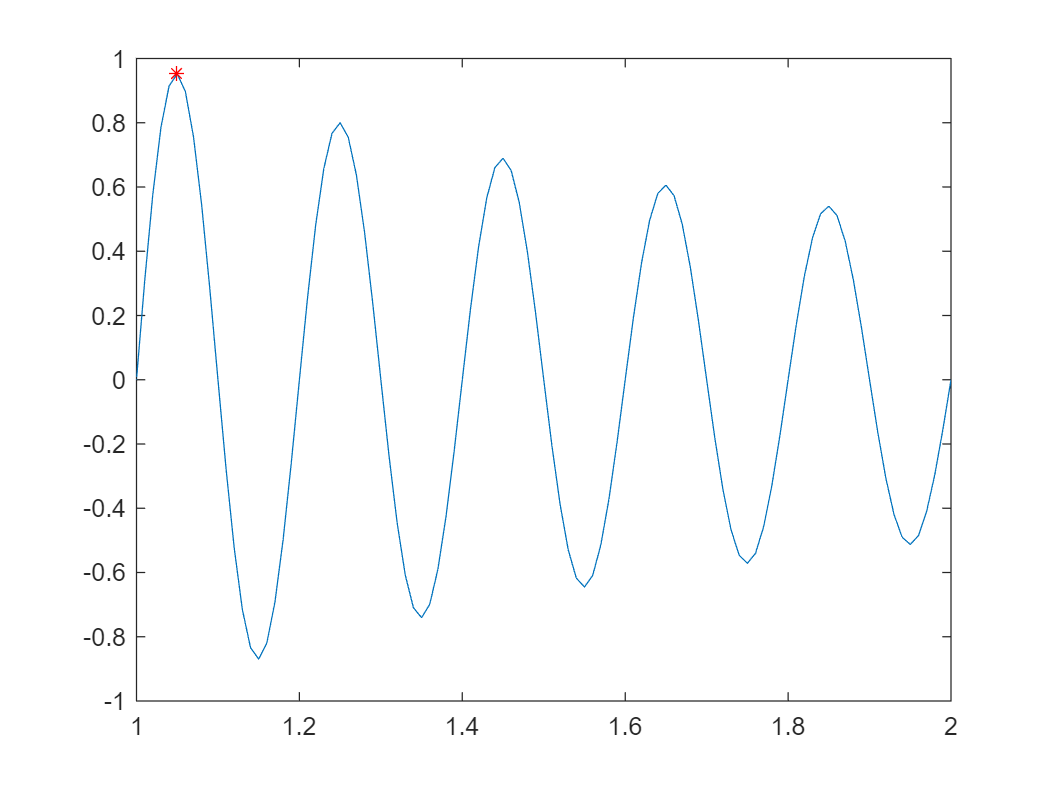

plot(zbest, fitnesszbest,'r*')

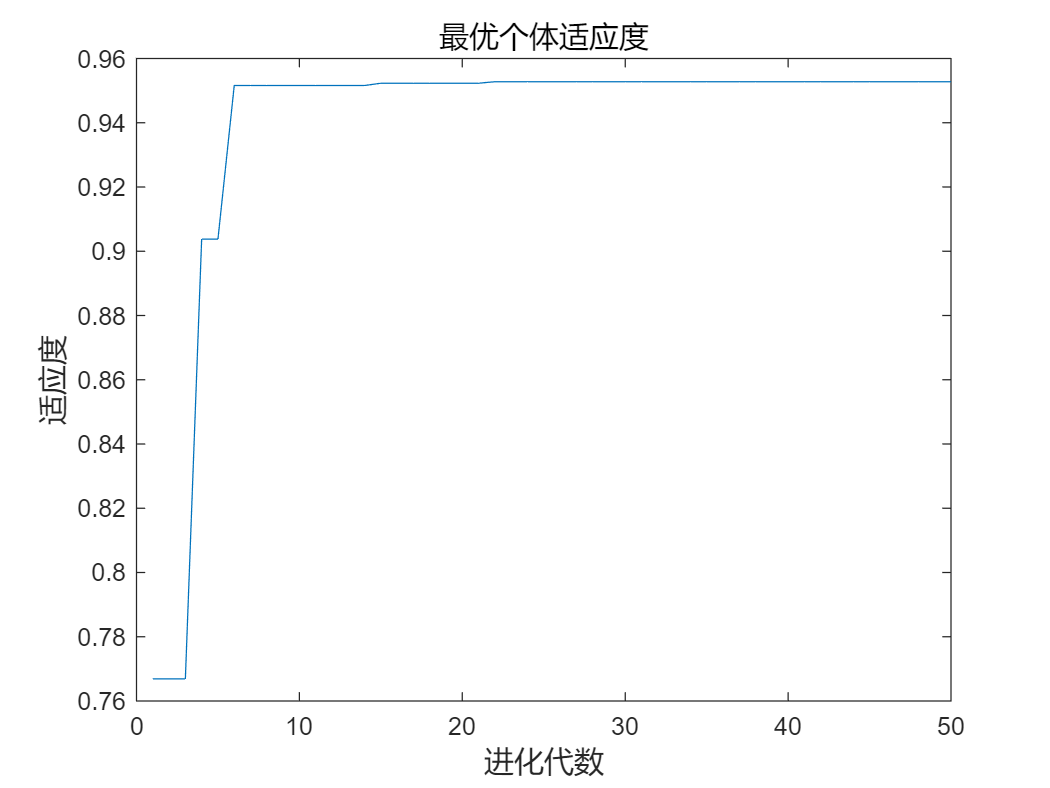

figure
plot(yy)
title('最优个体适应度','fontsize',12);
xlabel('进化代数','fontsize',12);ylabel('适应度','fontsize',12);

function y = fun(x)
y = sin(10*pi*x) ./ x;
end